#### Question 1

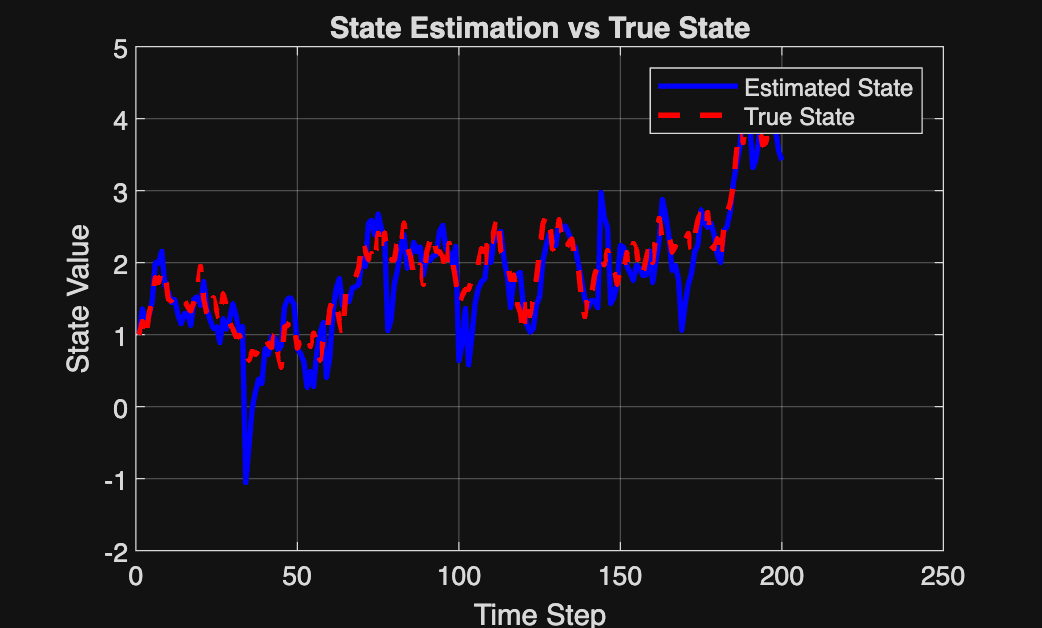

mu = 0;
n = 200;
sigma = sqrt(0.05);
noise = mu + sigma * randn(1, n);
v1 = mu + sqrt(1) * randn(1, n);

for k = 1:n
    v2(k) = sqrt(abs(cos(k))) * randn(1);
end

y = zeros(2, n);
x_est = zeros(1, n);
x_true(1) = 1;

y(:, 1) = [0 0]';
y(:, 2) = [3 1]';

for k = 1:length(noise)
    x_true(k+1) = x_true(k) + noise(k);
end

for k = 3:n
    H = [2 ; sin(k-1)];
    y(:, k) = H * x_true(k) + [v1(k) v2(k)]';
end 


x_est(1) = 1;
cov(1) = 1;
for k = 1:length(noise)-1
    H = [2 sin(k)]';
    R = [1 0; 0 abs(cos(k))];
    x_est_pred = x_est(k); % State Prediction
    cov_pred = cov(k) + 0.05; % Covariance Prediction
    kalman_gain = cov_pred * H' * inv(H * cov_pred * H' + R); % Kalman Gain
    x_est(k+1) = x_est_pred + kalman_gain * (y(:, k+1) - H * x_est_pred); % State Update
    cov(k+1) = (1 - kalman_gain * H) * cov_pred; % Covariance Update
end

figure;
plot(1:length(x_est), x_est, 'b-', 'LineWidth', 2); % Plot estimated state
hold on; 
plot(1:length(x_true), x_true, 'r--', 'LineWidth', 2); % Plot true state
xlabel('Time Step');
ylabel('State Value');
title('State Estimation vs True State'); 
legend('Estimated State', 'True State');
grid on; 
hold off;

#### Question 2

clear all
clc
Vm = 400;
Vt = 200;
alpham_ideal = 25.66 * pi/180;
alphat = 60 * pi / 180;
alpham = 40.66 * pi / 180;
ri = 10000;
N = 3;
tf = 46.78

tf = 46.7800

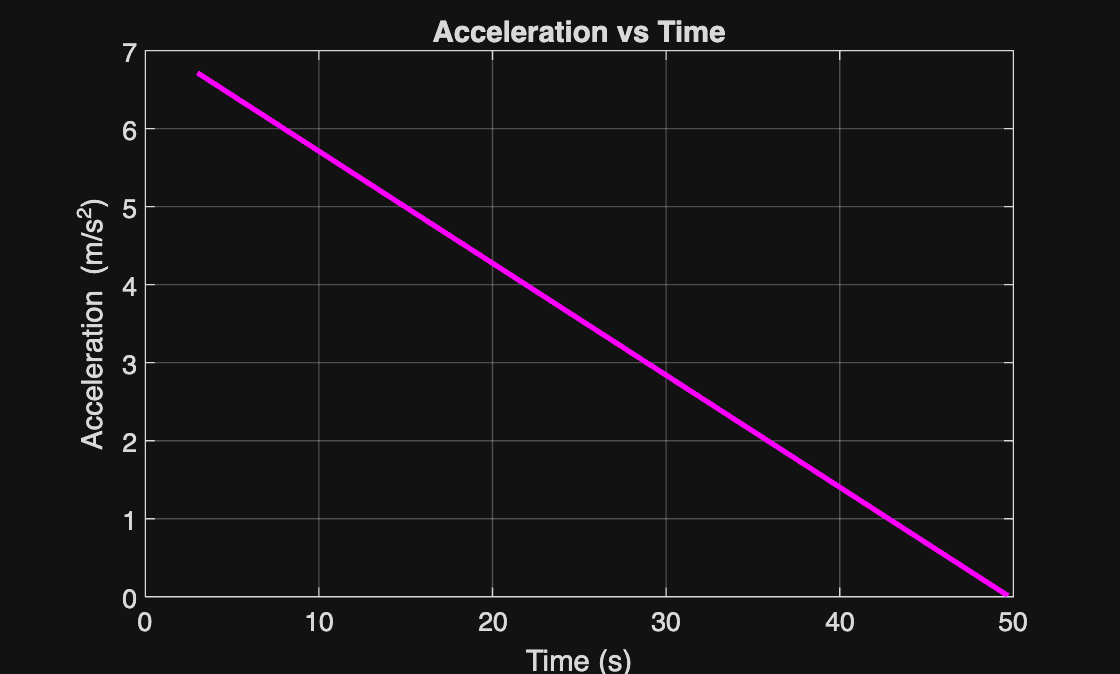

i_deviation = 15 * pi / 180;




t_new = 3:0.1:tf + 3;
am = (Vm * 15 * (pi / 180) * N * ((tf + 3 - t_new) / tf) .^ (N - 2)) / tf;
figure;
plot(t_new, am, 'm-', 'LineWidth', 2); 
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Acceleration vs Time');
grid on;


t = 0:0.1:3; 
t1 = 0:0.1:tf+3

t1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


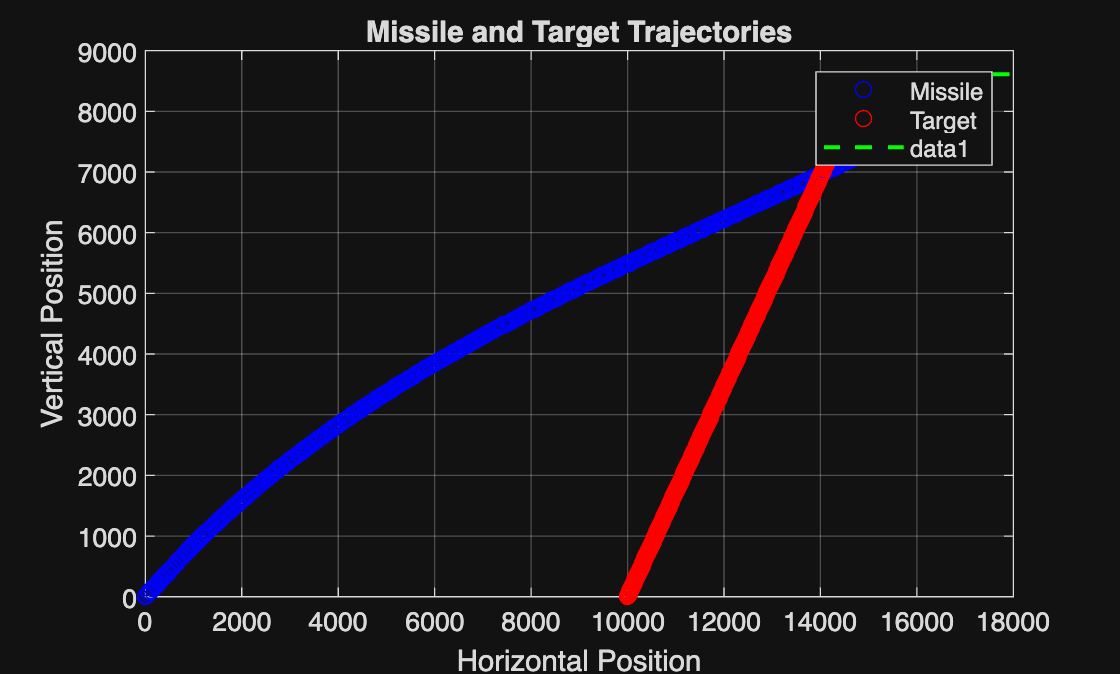

x_missile = Vm * cos(alpham_ideal + i_deviation) * t;
y_missile = Vm * sin(alpham_ideal + i_deviation) * t;
x_target = Vt * cos(alphat) * t1 + 10000;
y_target = Vt * sin(alphat) * t1;



deviation = i_deviation * (((tf - t_new + 3) / tf) .^ (N - 1));


for k = 1:length(t_new)
    x_missile(k + 31) = Vm * cos(alpham_ideal + deviation(k)) * t_new(k);
    y_missile(k + 31) = Vm * sin(alpham_ideal + deviation(k)) * t_new(k);
end

for k = 1:length(t_new)
    plot(x_missile(k), y_missile(k), 'bo'); 
    hold on;
    plot(x_target(k), y_target(k), 'ro');
    pause(0.1);
end
xlabel('Horizontal Position');
ylabel('Vertical Position');
title('Missile and Target Trajectories');
legend('Missile', 'Target');

end_point_missile = [x_missile(end), y_missile(end)];
end_point_target = [x_target(end), y_target(end)];
plot([end_point_missile(1), end_point_target(1)], [end_point_missile(2), end_point_target(2)], 'g--', 'LineWidth', 1.5);
grid on;